# Simulation Of Ground Acceleration Record

Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

%frequency vector
f = linspace(0,48,4096);

- select `bandwidth of the earthquake excitation`

zeta = 0.3;

- select the standard deviation of `earthquake excitation`

sigma = 0.35;

- select `dominant frequency of the earthquake excitation (Hz).`

fn = 10;

- select `value of the envelop function at 90 percent of the duration.`

T90 = 0.25;

- select `normalized duration time when ground motion achieves peak.`

eps = 0.4;

- **select **duration of ground motion;

tn = 60;

Calling this function

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

### Plot Function

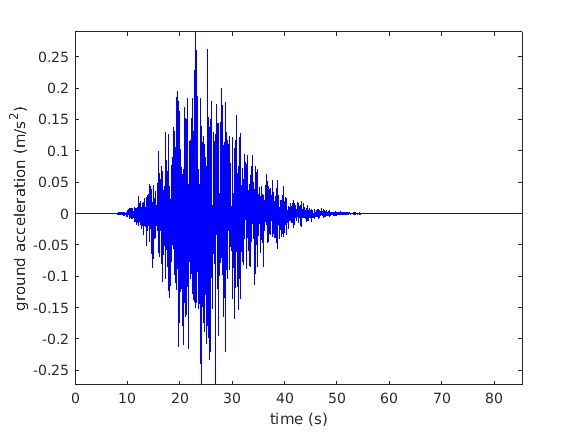

plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight

### Response Spectra

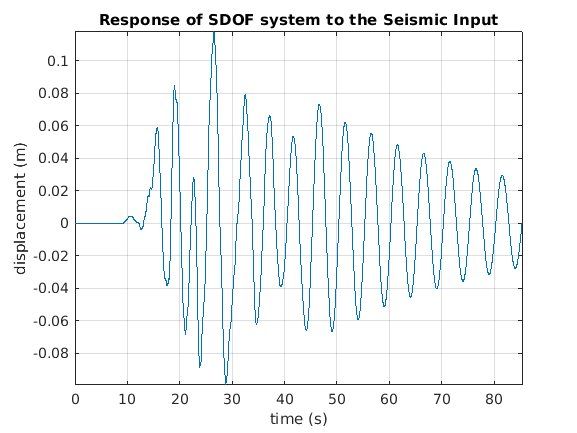

a = y ;  % acceleration for respective time step
% Plot the Accelerogram
%--------------------------------------------------------------------------
h = figure ;
set(h,'name','Accelerogram','numbertitle','off')
plot(t,a) ;
grid ;
title('EL centro Earthquake') ;
xlabel('time (Sec)') ;
ylabel('acceleration (g)') ;
a = a*9.8 ; % Changing Acceleration to m/s/s
%--------------------------------------------------------------------------
% Plot the Response of a SDOF system to the Seismic input
%--------------------------------------------------------------------------
xi = 2/100 ; % Relative damping
Tn = 5.;    % Natural period of SDOF system
y0 = [0;0] ; % Initial Conditions
% Response of SDOF System
[t,Y] = ode45(@odefun,t,y0,[],xi,Tn,t,a) ;
h = figure ;
set(h,'name','SDOF','numbertitle','off')
plot(t,Y(:,1)) ;
grid ;
title('Response of SDOF system to the Seismic Input') ;
ylabel('displacement (m)')
xlabel('time (s)')
axis tight ;

%--------------------------------------------------------------------------
% Plot the Response Spectra of the given Seismic Input
%--------------------------------------------------------------------------
disp('Please wait, it will take time to plot the response spectra ')

Please wait, it will take time to plot the response spectra 


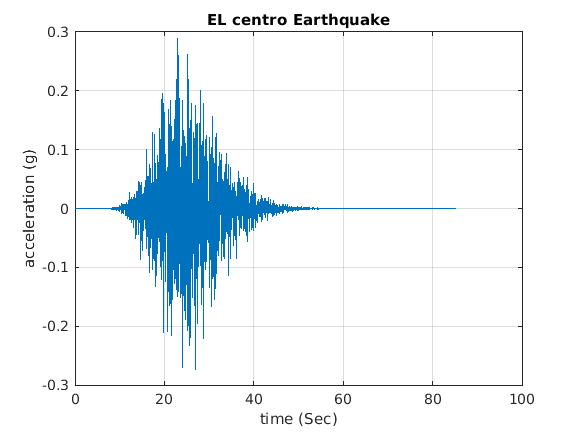

TnInitial = 0.01 ;
TnFinal = 10. ;
stepTn = 0.005 ;
Tn = TnInitial:stepTn:TnFinal ; % Natural periods of SDOF oscillator's
xi = 5/100 ;
y0 = [0;0] ;
Ymax = zeros(1,length(Tn)) ;
nsdof = 1 ;
for Tn = TnInitial:stepTn:TnFinal
    %Response of each SDOF system to the given Seismic Input
    [t,Y] = ode45(@odefun,t,y0,[],xi,Tn,t,a);  
    ymax = max(abs(Y(:,1))); % max. displacement
    Ymax(nsdof) = ymax;
    nsdof = nsdof+1 ;
end

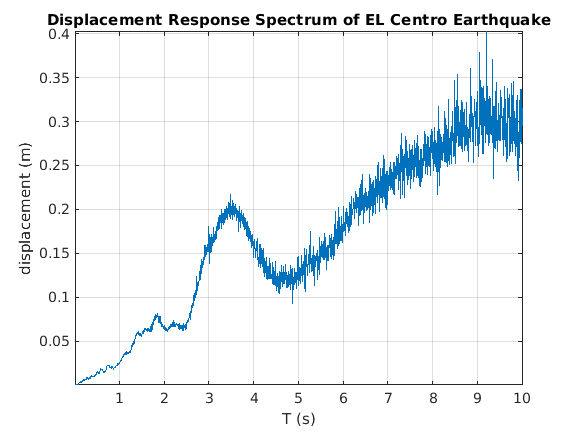

Tn = TnInitial:stepTn:TnFinal ;
h = figure ;
set(h,'name','ResponseSpectrum','numbertitle','off')
plot(Tn,Ymax);
grid;
title('Displacement Response Spectrum of EL Centro Earthquake')
ylabel('displacement (m)')
xlabel('T (s)')
axis tight ;

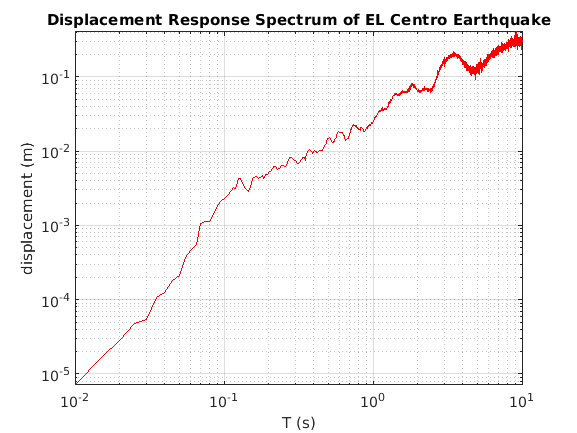

%
% Plot Response Spectrum on loglog scale
h = figure ;
set(h,'name','Log ResponseSpectrum','numbertitle','off')
loglog(Tn,Ymax,'r');
grid;
title('Displacement Response Spectrum of EL Centro Earthquake')
ylabel('displacement (m)')
xlabel('T (s)')
axis tight ;

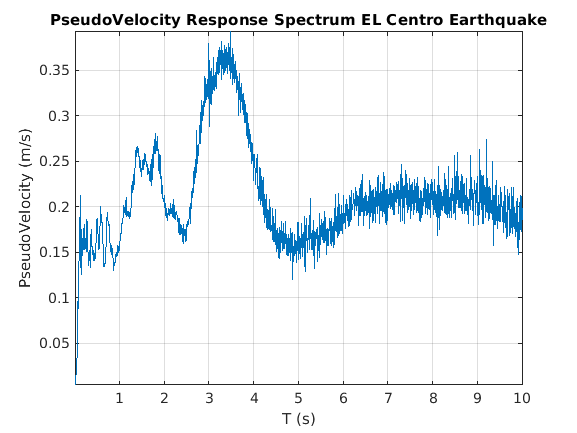

%--------------------------------------------------------------------------   
% Pseudo-velocity response spectrum
h = figure ;
set(h,'name','PseudoVelocity','numbertitle','off')
V = (2*pi./Tn).*Ymax;
plot(Tn,V);
grid;
title('PseudoVelocity Response Spectrum EL Centro Earthquake')
ylabel('PseudoVelocity (m/s)')
xlabel('T (s)')
axis tight ;

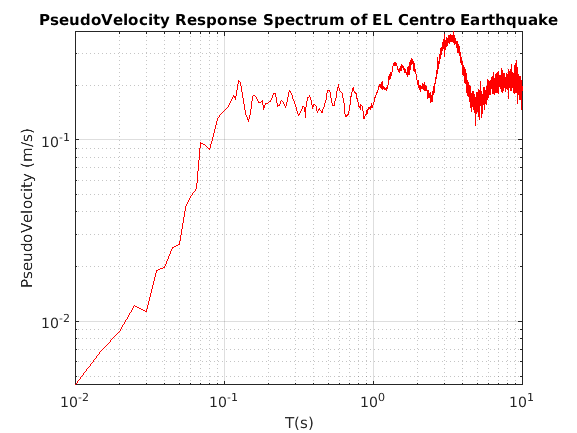

%
% Pseudo-velocity response spectrum on log scale
h = figure ;
set(h,'name','Log PseudoVelocity','numbertitle','off')
loglog(Tn,V,'r');
grid;
title('PseudoVelocity Response Spectrum of EL Centro Earthquake')
ylabel('PseudoVelocity (m/s)')
xlabel('T(s)')
axis tight ;

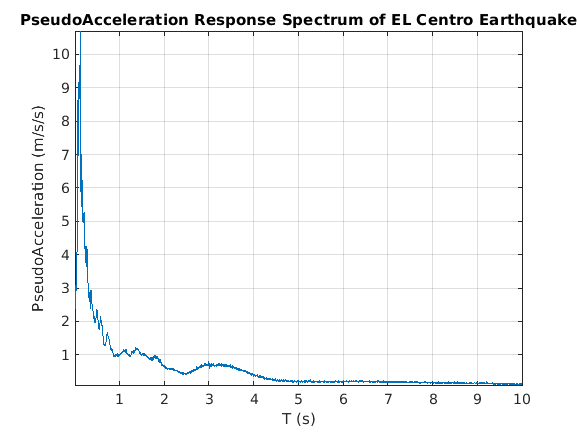

%--------------------------------------------------------------------------
% Pseudo-acceleration response spectrum
h = figure ;
set(h,'name','PseudoAcceleration','numbertitle','off')
A = (2*pi./Tn).*V;
plot(Tn,A);
grid;
title('PseudoAcceleration Response Spectrum of EL Centro Earthquake')
ylabel('PseudoAcceleration (m/s/s)')
xlabel('T (s)')
axis tight ;

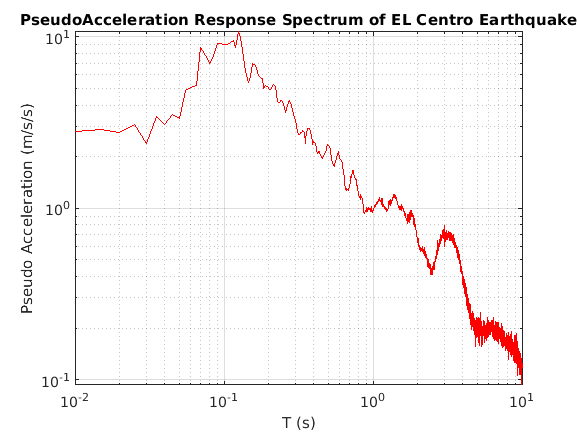

%
% Pseudo-acceleration response spectrum on log scale
h = figure ;
set(h,'name','Log PseudoAcceleration','numbertitle','off')
loglog(Tn,A,'r');
grid;
title('PseudoAcceleration Response Spectrum of EL Centro Earthquake')
ylabel('Pseudo Acceleration (m/s/s)')
xlabel('T (s)')
axis tight ;    

%--------------------------------------------------------------------------


#### Simulation Function:

function [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn)
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn) generate one time series
% corresponding to acceleration record from a seismometer. The function
% requires 7 inputs, and gives 2 outputs. The time series is generated in
% two steps: First a stationnary process is created based on the Kanai-
% Tajimi spectrum, then an envelope function is used to transform this 
% stationnary time series into a non-stationary record. For more
% information, see [1-3].
% [1] Lin, Y. K., & Yong, Y. (1987). Evolutionary Kanai-Tajimi earthquake
% models. Journal of engineering mechanics, 113(8), 1119-1137.
% [2] Rofooei, F. R., Mobarake, A., & Ahmadi, G. (2001). 
% Generation of artificial earthquake records with a nonstationary 
% KanaiTajimi model. Engineering Structures, 23(7), 827-837.
% [3] Guo, Y., & Kareem, A. (2016). 
% System identification through nonstationary data using TimeFrequency Blind
% Source Separation. Journal of Sound and Vibration, 371, 110-131.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% INPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sigma: [1 x 1 ]: standard deviation of the excitation.
% fn: [1 x 1 ]: dominant frequency of the earthquake excitation (Hz).
% zeta: [1 x 1 ]:  bandwidth of the earthquake excitation.
% f: [ 1 x M ]: frequency vector for the Kanai-tajimi spectrum.
% T90: [1 x 1 ]: value at 90 percent of the duration.
% eps: [1 x 1 ]: normalized duration time when ground motion achieves peak.
% tn: [1 x 1 ]: duration of ground motion.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% OUTPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% y: size: [ 1 x N ] : Simulated aceleration record
% t: size: [ 1 x N ] : time
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% EXAMPLE:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% f = linspace(0,40,2048);
% zeta = 0.3;
% sigma = 0.9;
% fn =5;
% T90 = 0.3;
% eps = 0.4;
% tn = 30;
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn);
% figure
% plot(t,y);axis tight
% xlabel('time(s)');
% ylabel('ground acceleration (m/s^2)')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% see also fitKT.m
% Author: Etienne Cheynet - modified: 23/04/2016

%% Initialisation
w = 2*pi.*f;
fs = f(end); dt = 1/fs;
f0= median(diff(f));
Nfreq = numel(f);
t = 0:dt:dt*(Nfreq-1);

%% Generation of the spectrum S
fn = fn *2*pi; % transformation in rad;
s0 = 2*zeta*sigma.^2./(pi.*fn.*(4*zeta.^2+1));
A = fn.^4+(2*zeta*fn*w).^2;
B = (fn.^2-w.^2).^2+(2*zeta*fn.*w).^2;
S = s0.*A./B; % single sided PSD


%% Time series generation - Monte Carlo simulation
A = sqrt(2.*S.*f0);
B =cos(w'*t + 2*pi.*repmat(rand(Nfreq,1),[1,Nfreq]));
x = A*B; % stationary process

%% Envelop function E
b = -eps.*log(T90)./(1+eps.*(log(T90)-1));
c = b./eps;
a = (exp(1)./eps).^b;
E = a.*(t./tn).^b.*exp(-c.*t./tn);

%% Envelop multiplied with stationary process to get y
y = x.*E;

end

ode function

function ydot = odefun(t,y,xi,Tn,t1,a2)
a = interp1(t1,a2,t); % Interpolate the data set (t1,a2) at time t
ydot = [y(2); -(4*pi*xi/Tn)*y(2)-(2*pi/Tn)^2*y(1)- a];
end